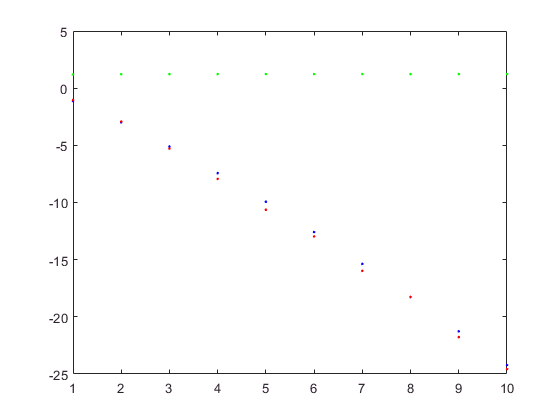

s=-1:0.1:1;
f=@(x)exp(x);
n=10;
err1=zeros(1,n);
err2=zeros(1,n);
err3=zeros(1,n);
for k=1:n
    err1(k)=max(f(s)-chebT(f,k,s));
    err2(k)=max(f(s)-chebU(f,k,s));
     err3(k)=max(f(s)-legendre(f,k,s));
end
plot(1:n,log(err1),'.b');
hold on;
plot(1:n,log(err2),'.r');
hold on;
plot(1:n,log(err3),'.g')

legendre(f,2,s)

ans =    0.8789 + 1.7578i   0.8953 + 1.7906i   0.9138 + 1.8276i   0.9345 + 1.8690i   0.9573 + 1.9147i   0.9823 + 1.9646i   1.0094 + 2.0189i   1.0387 + 2.0774i   1.0701 + 2.1403i   1.1037 + 2.2074i   1.1394 + 2.2788i   1.1773 + 2.3546i   1.2173 + 2.4346i   1.2594 + 2.5189i   1.3037 + 2.6075i   1.3502 + 2.7004i   1.3988 + 2.7976i   1.4495 + 2.8991i   1.5024 + 3.0048i   1.5575 + 3.1149i   1.6146 + 3.2293i
